clear all
parameters = [102 350 -69.71*10^6 1.205 20.75*10^6 69.71*10^6 8314 801 3137 ...
    851 101 10.1 294 1000 4183 294 339.7022 323.7669 0.0842 0.04377 0.011];

[A,B,C,D] = linearmodSS(parameters);
eig(A)

ans =    -0.0407
   -0.0005
   -0.0034


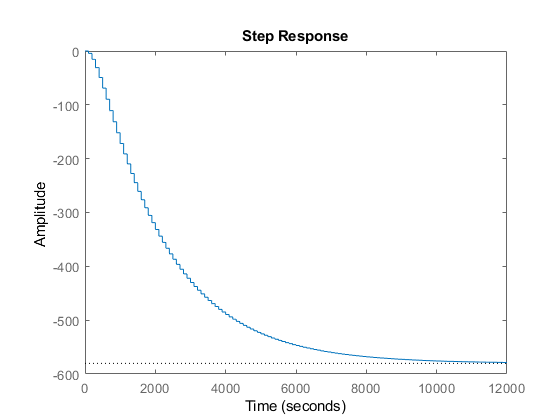


Aplant = A;
Bplant = B;
Tsam = 100;
sys = ss(A,B,C,D);
Gz = c2d(sys,Tsam);
step(Gz)

[Amod,Bmod,Cz,D] = ssdata(Gz);

Gzpk = zpk(Gz)


Gzpk =
 
  -4.3576 (z-0.01682) (z+0.8793)
  -------------------------------
  (z-0.017) (z-0.7129) (z-0.9508)
 
Sample time: 100 seconds
Discrete-time zero/pole/gain model.



Gs = tf(Gz)


Gs =
 
     -4.358 z^2 - 3.758 z + 0.06445
  ------------------------------------
  z^3 - 1.681 z^2 + 0.7061 z - 0.01152
 
Sample time: 100 seconds
Discrete-time transfer function.



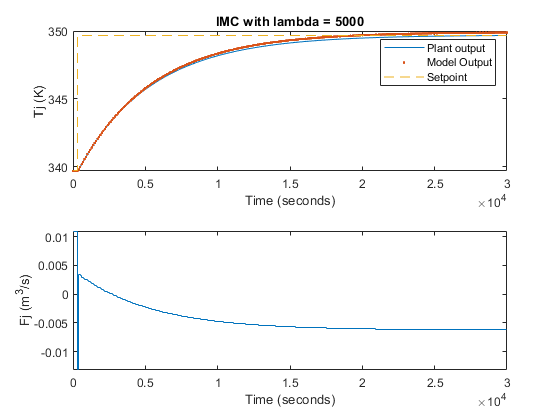

tbeng = 0;
deltaT = Tsam;
x0 = [0;0;0];
time = 0:Tsam:30000;
rsp = 10;
Tr_ss = 339.7022; % steady state value of output
Fj_ss = 0.011; % steady state value of input

y =  zeros(1,length(time)+2); % plant output
ym = zeros(1,length(time)+2); % model output
r = zeros(1,length(time)+2); % setpoint
rm = zeros(1,length(time)+2); % difference in deviation from setpoint (r)
u = zeros(1,length(time)+2); % manipulated input
e = zeros(1,length(time)+2); 
x =  zeros(3,length(time)+2); 
lambda = 5000; % tuning parameters
alpha = exp(-Tsam/lambda);

for k = 4:length(time)+2 % step change at time = 1
    if k < 6
        r(1,k) = 0; % each row operation (i) is used for each tuning parameter
    else 
        r(1,k) = rsp; % step change
    end
  
    
    ym(1,k) = modelresponse(ym(1,k-1), ym(1,k-2), ym(1,k-3), u(1,k-1), u(1,k-2), u(1,k-3));
    e(1,k) = y(1,k) - ym(1,k); 
    rm(1,k) = r(1,k) - e(1,k);
    
    u(1,k) = IMC(u(1,k-1),u(1,k-2),alpha,rm(1,k),rm(1,k-1),rm(1,k-2),rm(1,k-3));
   
[~,xnew] = ode45(@(t,x) lincstrplant(t,x,Aplant,Bplant,u(1,k)),[time(k-2) time(k-2)+deltaT], x0); % ODE45 function
x(:,k+1) = xnew(end,:);

y(1,k+1) = Cz*x(:,k+1); % output as last value of xnew
%y(1,k+1) = Cz*xnew(:,end); % output as last value of xnew
x0(:,1)= xnew(end,:)'; % assigning states variables as input for next iteration
end
figure(1);
subplot(2,1,1)
plot(time,y(1,3:end-1)+Tr_ss,time,ym(1,3:end)+Tr_ss,'.')
hold on
stairs(time,r(1,3:end)+Tr_ss,'--')
hold off
xlabel('Time (seconds)')
ylabel('Tj (K)')
legend('Plant output','Model Output','Setpoint')
title(['IMC with lambda = ', num2str(lambda)])

subplot(2,1,2)
stairs(time,u(1,3:end)+Fj_ss)
xlabel('Time (seconds)')
ylabel('Fj (m^3/s)')

## IMC with Model Error

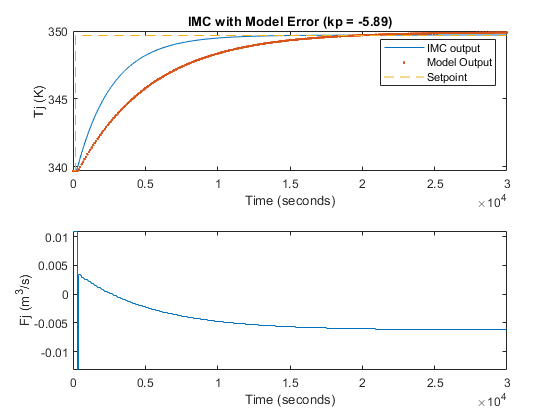

Bplant1 = [0 0;0 0;-5.894 -1.4735];

yout = cell(2,1);
ymout = cell(2,1);
uinput = cell(2,1);

for i = 1:2
y1 =  zeros(1,length(time)+2); % plant output
ym1 = zeros(1,length(time)+2); % model output
r1 = zeros(1,length(time)+2); % setpoint
rm1 = zeros(1,length(time)+2); % difference in deviation from setpoint (r)
u1 = zeros(1,length(time)+2); % manipulated input
e1 = zeros(1,length(time)+2); 
x1 = zeros(3,length(time)+2); 
x0 = [0;0;0];

for k = 4:length(time)+3 % step change at time = 1
    if k < 6
        r1(1,k) = 0; % each row operation (i) is used for each tuning parameter
    else 
        r1(1,k) = rsp; % step change
    end
    % each row operation (i) is used for each tuning parameter
    ym1(1,k) = modelresponse(ym1(1,k-1), ym1(1,k-2), ym1(1,k-3), u1(1,k-1), u1(1,k-2), u1(1,k-3));
    e1(1,k) = y1(1,k) - ym1(1,k); 
    rm1(1,k) = r1(1,k) - e1(1,k);
    u1(1,k) = IMC(u1(1,k-1),u1(1,k-2),alpha,rm1(1,k),rm1(1,k-1),rm1(1,k-2),rm1(1,k-3));
   
[~,xnew1] = ode45(@(t,x) lincstrplant(t,x,Aplant,Bplant1(:,i),u1(1,k)),[time(k-3) time(k-3)+deltaT], x0(:,1)); % ODE45 function
x1(:,k+1) = xnew1(end,:);

y1(1,k+1) = Cz*x1(:,k+1);
x0(:,1)= xnew1(end,:)'; % assigning states variables as input for next iteration
end
yout{i} = y1;
ymout{i} = ym;
uinput{i} = u;
end

figure(2);
subplot(2,1,1)
plot(time,yout{1}(1,4:end-1)+Tr_ss,time,ymout{1}(1,3:end)+Tr_ss,'.')
hold on
stairs(time,r1(1,4:end)+Tr_ss,'--')
hold off
xlabel('Time (seconds)')
ylabel('Tj (K)')
legend('IMC output','Model Output','Setpoint')
title('IMC with Model Error (kp = -5.89)')

subplot(2,1,2)
stairs(time,uinput{1}(1,3:end)+Fj_ss)
xlabel('Time (seconds)')
ylabel('Fj (m^3/s)')

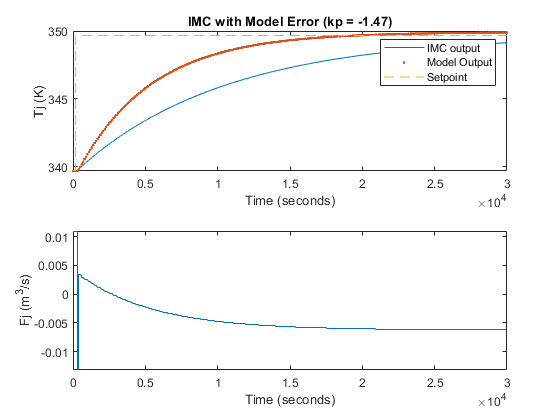


% Plots of Kp = -0.67

figure(3);
subplot(2,1,1)
plot(time,yout{2}(1,4:end-1)+Tr_ss,time,ymout{2}(1,3:end)+Tr_ss,'.')
hold on
stairs(time,r1(1,4:end)+Tr_ss,'--')
hold off
xlabel('Time (seconds)')
ylabel('Tj (K)')
legend('IMC output','Model Output','Setpoint')
title('IMC with Model Error (kp = -1.47)')


subplot(2,1,2)
stairs(time,uinput{2}(1,3:end)+Fj_ss)
xlabel('Time (seconds)')
ylabel('Fj (m^3/s)')

## Nonlinear Simulation

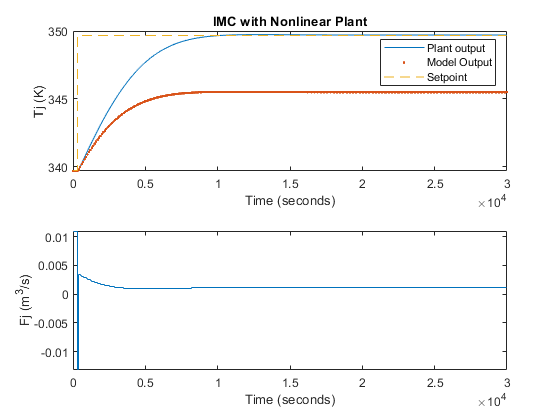

parameters2 = [102 350 -69.71*10^6 8.01 20.75*10^6 69.71*10^6 8314 801 3137 ...
    851 101 10.1 294 1000 4183 0.0842 339.7022 323.7669  0.04377 0.011];

y3 =  zeros(1,length(time)+2); % plant output
ym3 = zeros(1,length(time)+2); % model output
r3 = zeros(1,length(time)+2); % setpoint
rm3 = zeros(1,length(time)+2); % difference in deviation from setpoint (r)
u3 = zeros(1,length(time)+2); % manipulated input
e3 = zeros(1,length(time)+2); 
x3 =  zeros(3,length(time)+2); 
x0 = [0;0;0];

lambda = 5000; % tuning parameters
alpha = exp(-Tsam/lambda);

for k = 4:length(time)+2 % step change at time = 1
    if k < 6
        r3(1,k) = 0; % each row operation (i) is used for each tuning parameter
    else 
        r3(1,k) = rsp; % step change
    end
  
    
    ym3(1,k) = modelresponse(ym3(1,k-1), ym3(1,k-2), ym3(1,k-3), u3(1,k-1), u3(1,k-2), u3(1,k-3));
    e3(1,k) = y3(1,k) - ym3(1,k); 
    rm3(1,k) = r3(1,k) - e3(1,k);
    
    u3(1,k) = IMC(u3(1,k-1),u3(1,k-2),alpha,rm3(1,k),rm3(1,k-1),rm3(1,k-2),rm3(1,k-3));
  
[~,xnew3] = ode45(@(t,x) NLcstrplant(t,x,parameters2,u3(1,k)),[time(k-2) time(k-2)+deltaT], x0); % ODE45 function
x3(:,k+1) = xnew3(end,:);

y3(1,k+1) = Cz*x3(:,k+1); % output as last value of xnew
%y(1,k+1) = Cz*xnew(:,end); % output as last value of xnew
x0(:,1)= xnew3(end,:)'; % assigning states variables as input for next iteration
end
figure(1);
subplot(2,1,1)
plot(time,y3(1,3:end-1)+Tr_ss,time,ym3(1,3:end)+Tr_ss,'.')
hold on
stairs(time,r3(1,3:end)+Tr_ss,'--')
hold off
xlabel('Time (seconds)')
ylabel('Tj (K)')
legend('Plant output','Model Output','Setpoint')
title(['IMC with Nonlinear Plant'])

subplot(2,1,2)
stairs(time,u3(1,3:end)+Fj_ss)
xlabel('Time (seconds)')
ylabel('Fj (m^3/s)')

## IMC Function

function uk = IMC(uk1,uk2,alpha,rk,rk1,rk2,rk3)

uk = (uk1*(alpha+0.01682)) - uk2*(0.01682*alpha) - 0.12211*(1-alpha)*(rk - 1.681*rk1 ...
    + 0.7061*rk2 - 0.01152*rk3);
end

## Model

function ykm = modelresponse(yk1,yk2,yk3,uk1,uk2,uk3)
ykm = 1.681*yk1 - 0.7061*yk2 + 0.01152*yk3 - 4.358*uk1 - 3.758*uk2 + 0.06445*uk3;
end

